# Flux & Force Harmonic order Study

### Field 데이터 불러오기

path='Z:\pyleecan_GUI_version\2023_01_18-10h42min32s_FEMM_Toyota_Prius';
% pyleecan=load(strcat(path,'\',"Result.mat"))
load(strcat(path,'\',"Result.mat"))

p=4 % 극상수 

### 함수 호출 순서 

1) 2D FFT : fcn) plot_2d_fft_positive(필드 데이터 변수명, 극수/2, "단위")

2) Force density  계산: fcn)force_densitiy_calc(방사방향 자속밀도분포,접선방향자속밀도분포)

3) Local Force 계산, Torque (Global Force) 계산  - fcn)Force_torque_calc(방사방향 표면전자기력밀도, 접선방향 표면전자기력밀도, 공극반지름, 적층길이)

### 1) 2D FFT

B_tan_i=plot_2d_fft_positive(B_tan,p,"[ T ]");


fft_1d_gif("Result.mat",B_rad,4,120)


### 2) 표면전자기력밀도 계산

[fr,ft] = force_densitiy_calc(B_rad,B_tan); % Air-gap Surface Force 

ft_i=plot_2d_fft_positive(ft,p,"[N/m^{2}]"); %Force Density 2D FFT (tangential)
fr_i=plot_2d_fft_positive(fr,p,"[N/m^{2}]"); %Force Density 2D FFT (radial)



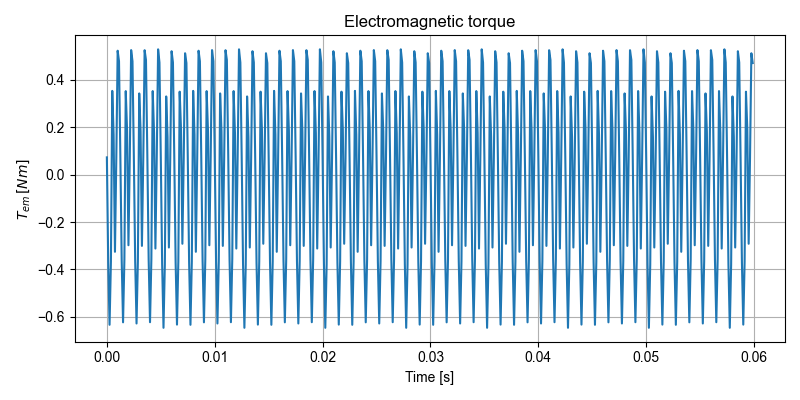

### 3) 표면 전자기력 & Torque in MST  계산

Stator_Rint=0.08095 %[m]
Rotor_Rext=0.0802   %[m]
radius=(0.08095-(Stator_Rint-Rotor_Rext)/2); %[m]
Lstk=0.08382; %[m]

[Fr,Ft,EM_Torque]=Force_torque_calc(fr,ft,radius,Lstk);
plot(time,EM_Torque);


